# GWSC_Lab2

## Lab topic 2 - 2021/02/23

### Antenna patterns

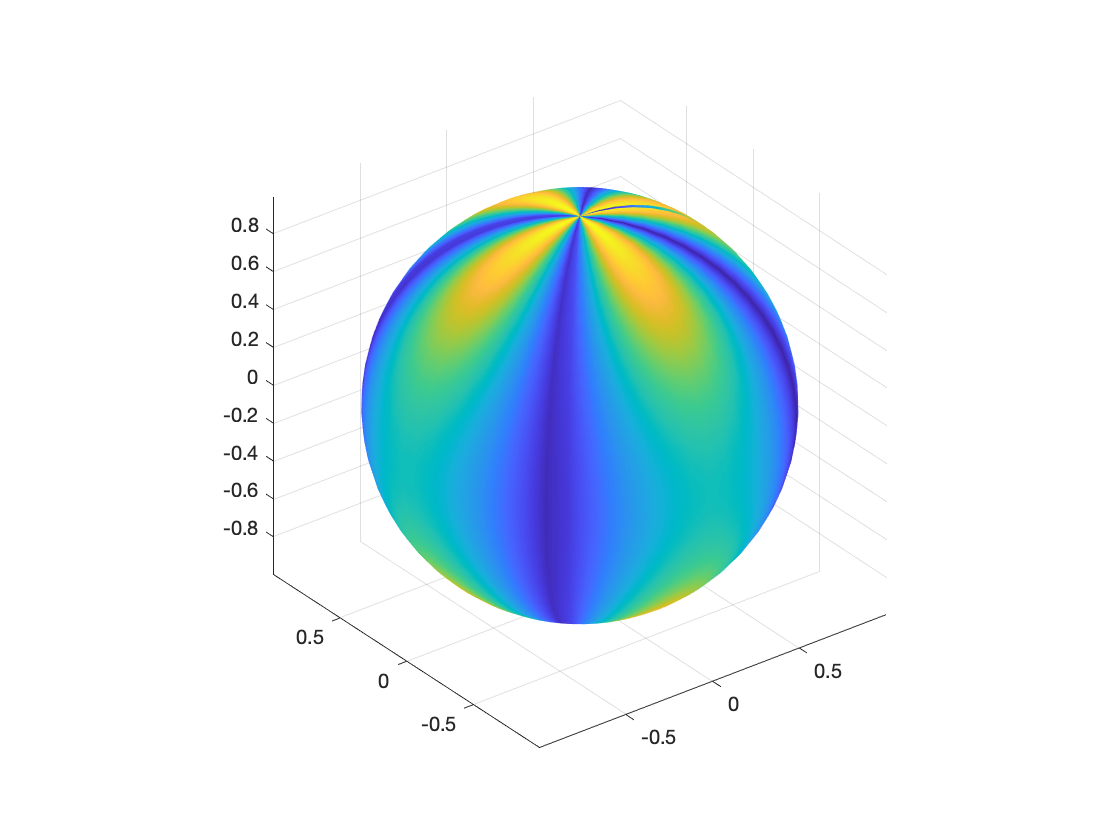

thetaVec = 0:0.1:2*pi; % Azimuthal angle
phiVec = 0:0.1:pi; % polar angle
fp = @(x,y) formulafp(x,y);
skyplot(thetaVec,phiVec,fp);

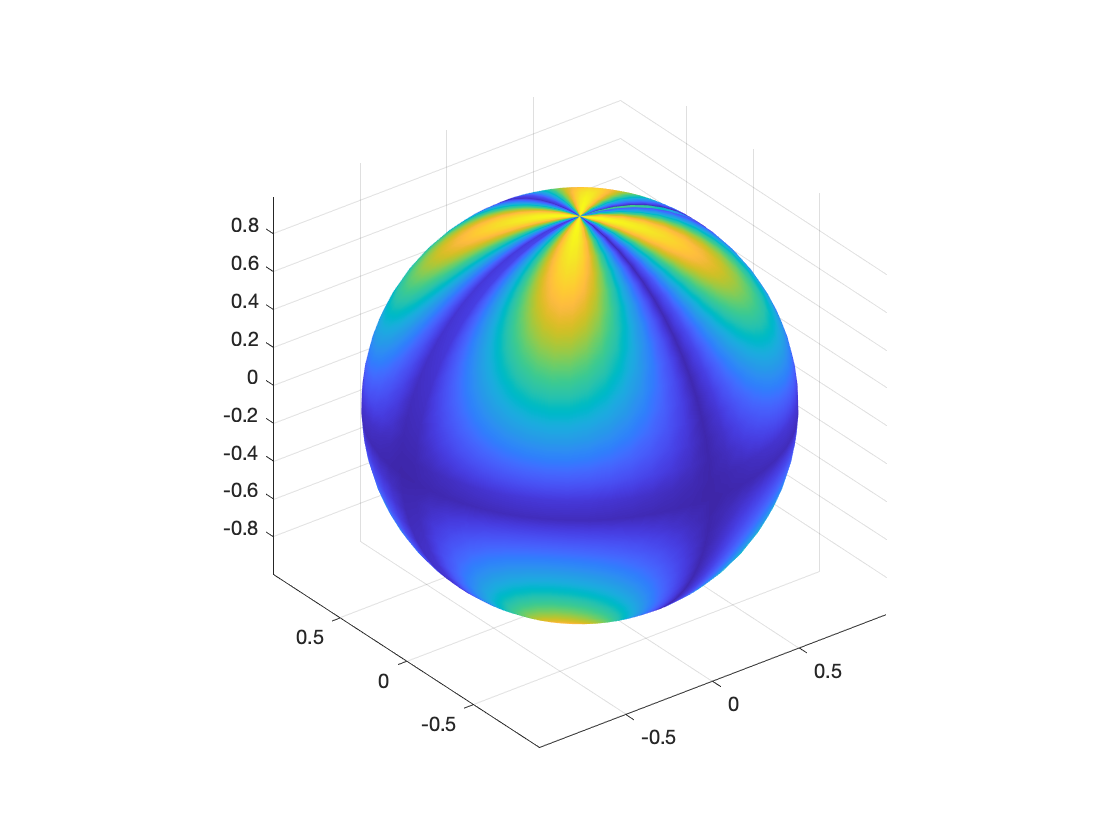

fc = @(a,b) formulafc(a,b);
skyplot(thetaVec,phiVec,fc);

function fp = formulafp(theta,phi)
% calculate F_+ antenna pattern.
% formulafp(A,P)
% A,P is azimuthal and polar angle separately.

% QYQ 2021/02/24

fp = 1/2 * (1 + cos(phi)^2) * cos(2 * theta);
end

function fc = formulafc(theta,phi)
% Calculate the F_x antenna pattern.

fc = cos(phi) * sin(2 * theta);
end

function [] = skyplot(thetaVec,phiVec,fHandle)
%Plot a function of sky angles on the unit sphere
%SKYPLOT(A,D,F)
%A and D are the vector of azimuthal and polar angle values respectively. F
%is the handle to the function of A and D that is to be plotted on the
%sphere. The polar angle range is 0 (z-axis) to Pi (negative z-axis). The
%angles are assumed to be in radian.

% Generate the X,Y,Z meshes corresponding to the azimuthal and polar angles.
[A,D] = meshgrid(thetaVec,phiVec);
X = sin(D).*cos(A);
Y = sin(D).*sin(A);
Z = cos(D);

fVals = zeros(length(phiVec),length(thetaVec));

for lp1 = 1:length(thetaVec)
    for lp2 = 1:length(phiVec)
        fVals(lp2,lp1) = fHandle(thetaVec(lp1),phiVec(lp2));
    end
end

% Plot
surf(X,Y,Z,abs(fVals));
shading interp;
axis equal

end